# Práctica 6: Sistemas diferenciales y en diferencias

Alvarado Ángeles Franciso Javier

Rubio Guerrero Edgar Miguel

## Parte 1

se tiene el sistema diferencial $\ddot{y}(t)+2\dot{y}(t)+3y(t)=\dot{x}(t)-x(t)$

donde $x(t)=cos(2t)u(t), y(0^-)=1, \dot{y}(0^-)=1$ y se requiere:

- La función de transferencia del sistema

- La respuesta al impulso

- La respuesta a entrada cero

- La respuesta a estado cero

- La respuesta total

- Las gráficas de cada caso

Para el problema se definen las variables a utilizar en cada función:

a=[3 2 1];
b=[-1 1];
ciy=[1 1];
syms t;
xi=cos(2.*t).*heaviside(t);
t0=10;

Para la función de transferencia:

funt=functrans(a,b,ciy)

 
APLICAMOS TRANSFORMADA DE LAPLACE
 
                     2
3 Y(s) + 2 s Y(s) + s  Y(s)

=
s X(s) - X(s)

 
DESPEJAMOS Y(s)
 
Y(s)=
X(s) (s - 1)
------------
 2
s  + 2 s + 3

 
Sabiendo que Y(s)=X(s)H(s) y siendo H(s) la función de transferencia
 
 
H(s)=
 
    s - 1
------------
 2
s  + 2 s + 3

 
Aplicamos transformada inversa, asi la solución es
 
H(t)=
        /                  sqrt(2) sin(sqrt(2) t) \   sqrt(2) exp(-t) sin(sqrt(2) t)
exp(-t) | cos(sqrt(2) t) - ---------------------- | - ------------------------------
        \                             2           /                  2



$$funt(t) = {\mathrm{e}}^{-t}\,\left(\cos\left(\sqrt{2}\,t\right)-\frac{\sqrt{2}\,\sin\left(\sqrt{2}\,t\right)}{2}\right)-\frac{\sqrt{2}\,{\mathrm{e}}^{-t}\,\sin\left(\sqrt{2}\,t\right)}{2}$$

La respuesta al impulso es obtenida mediante la función:

 
APLICAMOS TRANSFORMADA DE LAPLACE y subtituimos condiciones iniciales
 
                     2
3 Y(s) + 2 s Y(s) + s  Y(s)

=
s X(s) - X(s)

 
SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA
 
                     2
3 Y(s) + 2 s Y(s) + s  Y(s)

=
s - 1

 
DESPEJAMOS Y(s)
 
Y(s)=
    s - 1
------------
 2
s  + 2 s + 3

 
DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(s)
 
Y(s)=
    s - 1
------------
 2
s  + 2 s + 3

 
Aplicamos transformada inversa, asi la solución es
 
y(t)=
exp(-t) (cos(sqrt(2) t) - sqrt(2) sin(sqrt(2) t))



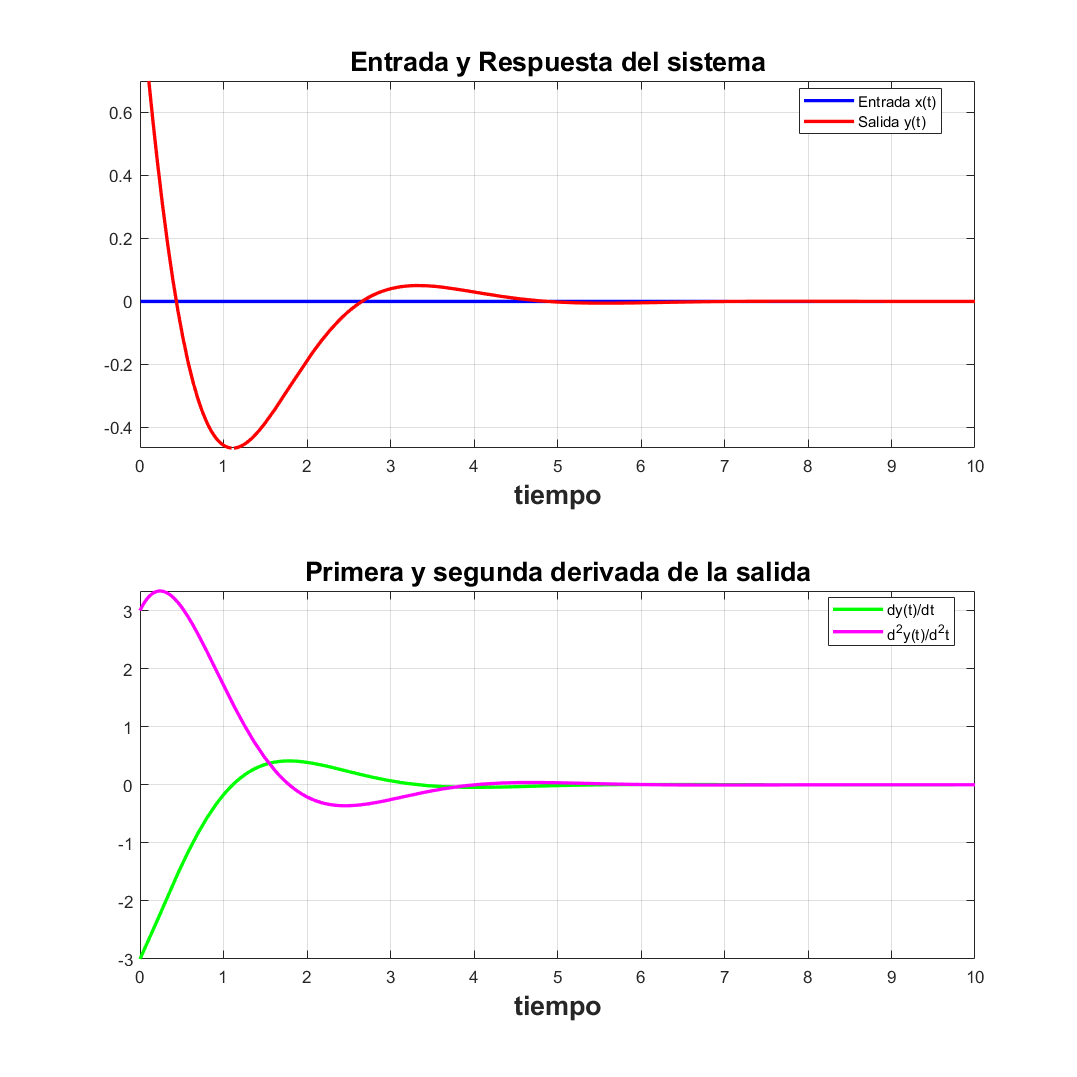

[imp,dimp,ddimp]=impulsola(a,b,ciy,t0,1);

Para encontrar la respuesta a estado cero se puede utilizar la siguiente función;

 
APLICAMOS TRANSFORMADA DE LAPLACE y subtituimos condiciones iniciales
 
                         2
3 Y(s) - s + 2 s Y(s) + s  Y(s) - 3

=
s X(s) - X(s)

 
SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA
 
                         2
3 Y(s) - s + 2 s Y(s) + s  Y(s) - 3

=
0

 
DESPEJAMOS Y(s)
 
Y(s)=
    s + 3
------------
 2
s  + 2 s + 3

 
DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(s)
 
Y(s)=
    s + 3
------------
 2
s  + 2 s + 3

 
Aplicamos transformada inversa, asi la solución es
 
y(t)=
exp(-t) (cos(sqrt(2) t) + sqrt(2) sin(sqrt(2) t))



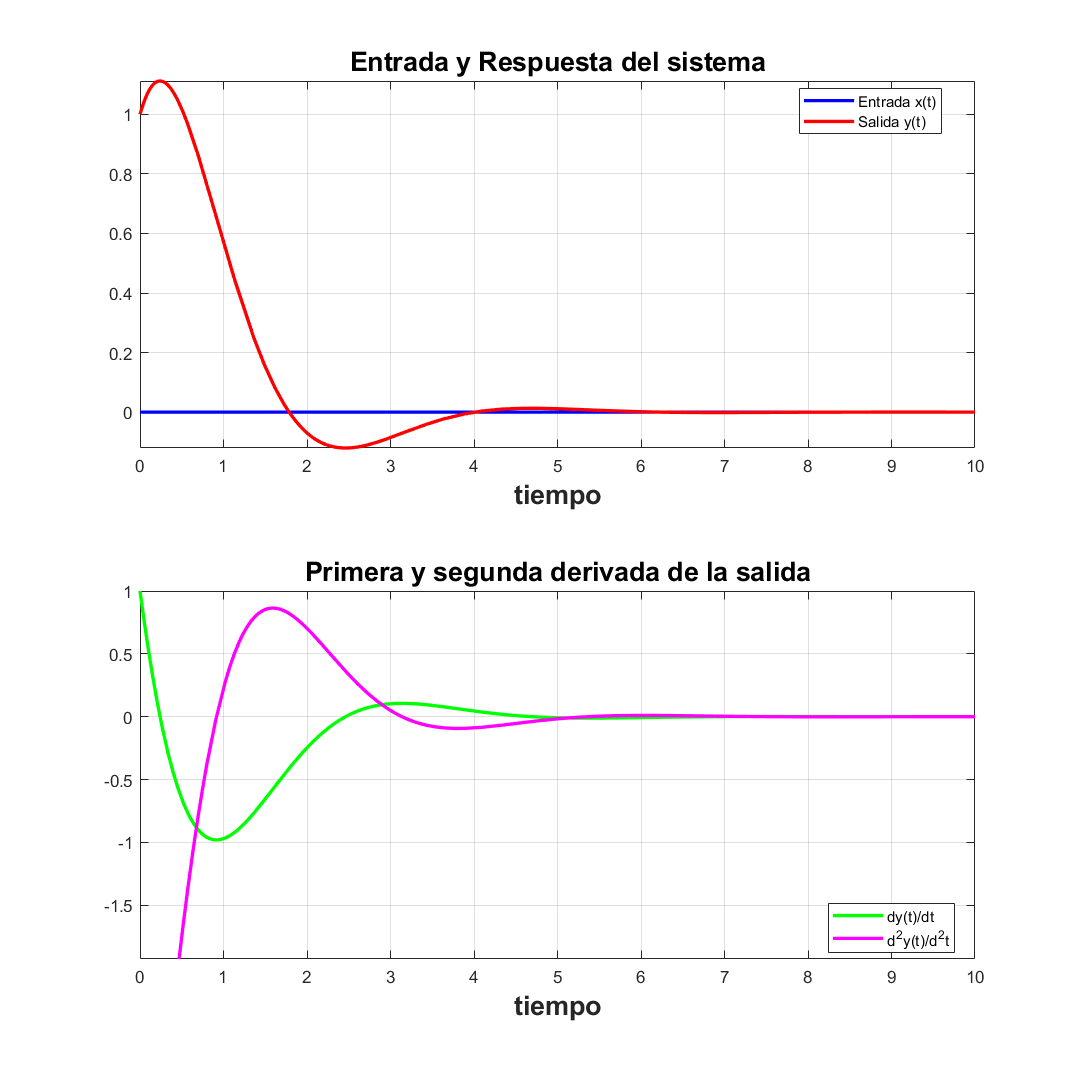

[en0,den0,dden0]=entradacerola(a,b,ciy,xi,t0,2);

Para la respuesta a estado cero:

 
APLICAMOS TRANSFORMADA DE LAPLACE y subtituimos condiciones iniciales
 
                     2
3 Y(s) + 2 s Y(s) + s  Y(s)

=
s X(s) - X(s)

 
SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA
 
                     2
3 Y(s) + 2 s Y(s) + s  Y(s)

=
   2
  s         s
------ - ------
 2        2
s  + 4   s  + 4

 
DESPEJAMOS Y(s)
 
Y(s)=
         s (s - 1)
---------------------------
 4      3      2
s  + 2 s  + 7 s  + 8 s + 12

 
DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(s)
 
Y(s)=
9 s    4     9 s    3
--- - --     --- - --
 17   17      17   17
-------- - ------------
  2         2
 s  + 4    s  + 2 s + 3

 
Aplicamos transformada inversa, asi la solución es
 
y(t)=
                                  /                  2 sqrt(2) sin(sqrt(2) t) \
                          exp(-t) | cos(sqrt(2) t) - ------------------------ | 9
cos(2 t) 9   sin(2 t) 2           \                              3            /
---------- - ---------- - -------------------------------------------------------
  

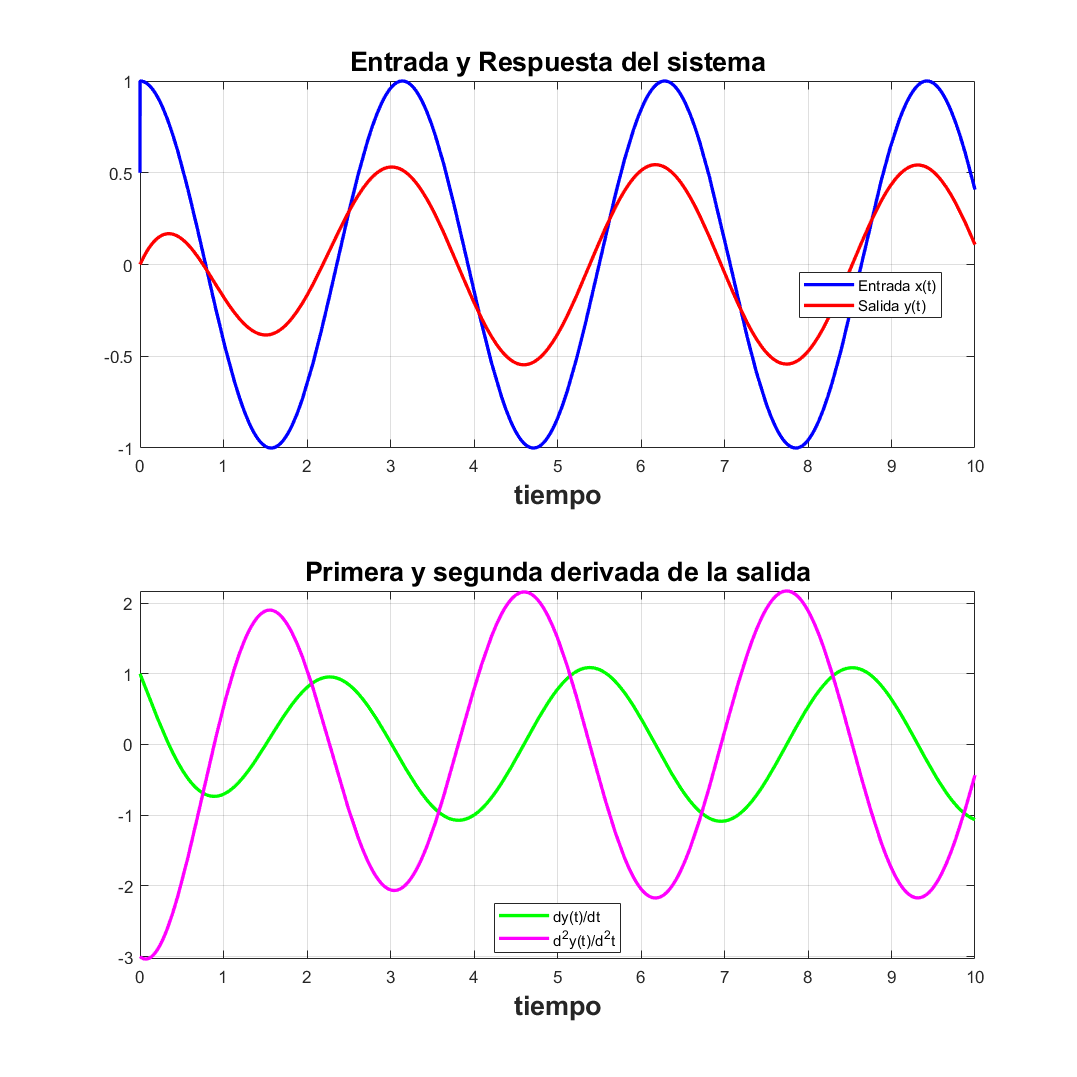

[es0,des0,ddes0]=estadocerola(a,b,ciy,xi,t0,3);

Utilizando la función original se puede encontrar la respuesta total

 
APLICAMOS TRANSFORMADA DE LAPLACE y subtituimos condiciones iniciales
 
                         2
3 Y(s) - s + 2 s Y(s) + s  Y(s) - 3

=
s X(s) - X(s)

 
SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA
 
                         2
3 Y(s) - s + 2 s Y(s) + s  Y(s) - 3

=
   2
  s         s
------ - ------
 2        2
s  + 4   s  + 4

 
DESPEJAMOS Y(s)
 
Y(s)=
     3      2
    s  + 4 s  + 3 s + 12
---------------------------
 4      3      2
s  + 2 s  + 7 s  + 8 s + 12

 
DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(s)
 
Y(s)=
9 s    4     8 s   54
--- - --     --- + --
 17   17      17   17
-------- + ------------
  2         2
 s  + 4    s  + 2 s + 3

 
Aplicamos transformada inversa, asi la solución es
 
y(t)=
                                  /                  23 sqrt(2) sin(sqrt(2) t) \
                          exp(-t) | cos(sqrt(2) t) + ------------------------- | 8
cos(2 t) 9   sin(2 t) 2           \                              8             /
---------- - ---------- + -----------

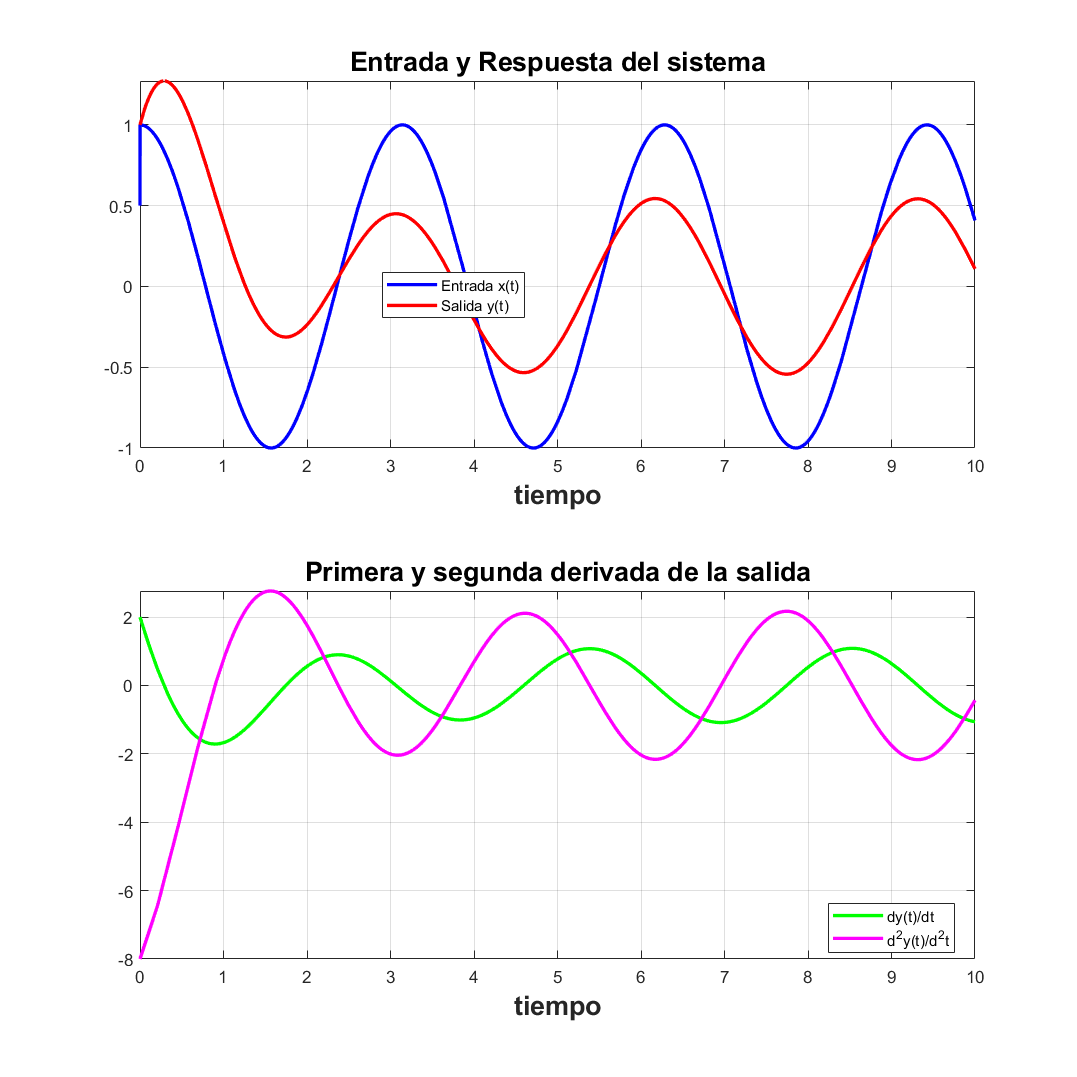

[rt,drt,ddrt]=laplace20(a,b,ciy,xi,t0,4);

Para encontrar la respuesta total al escalon con condiciones iniciales cero se utiliza:

 
APLICAMOS TRANSFORMADA DE LAPLACE y subtituimos condiciones iniciales
 
                     2
3 Y(s) + 2 s Y(s) + s  Y(s)

=
s X(s) - X(s)

 
SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA
 
                     2
3 Y(s) + 2 s Y(s) + s  Y(s)

=
    1
1 - -
    s

 
DESPEJAMOS Y(s)
 
Y(s)=
      s - 1
----------------
    2
s (s  + 2 s + 3)

 
DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(s)
 
Y(s)=
    s   5
    - + -
    3   3       1
------------ - ---
 2             3 s
s  + 2 s + 3

 
Aplicamos transformada inversa, asi la solución es
 
y(t)=
exp(-t) (cos(sqrt(2) t) + 2 sqrt(2) sin(sqrt(2) t))   1
--------------------------------------------------- - -
                         3                            3



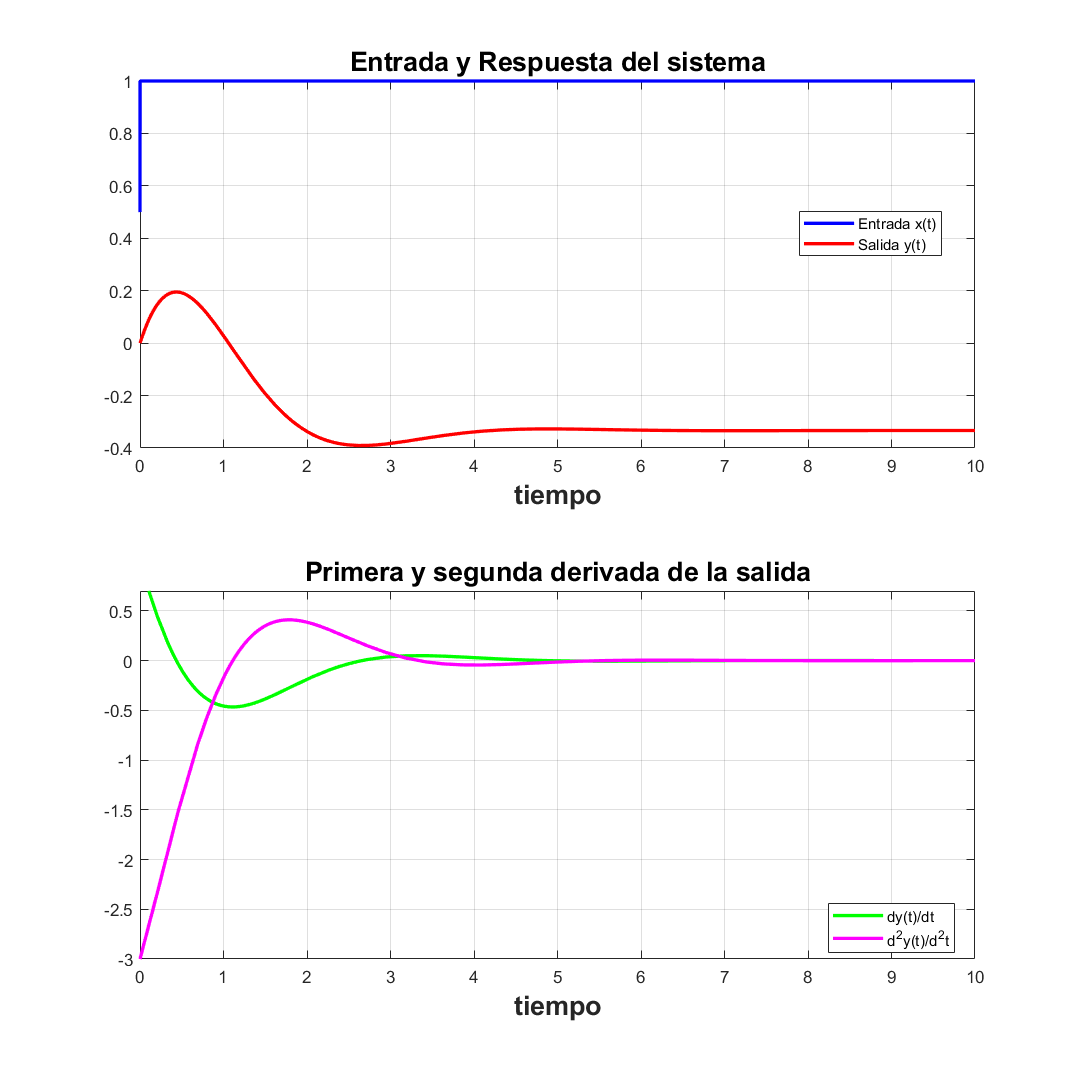

[te,dte,ddte]=totesc(a,b,ciy,t0,6);

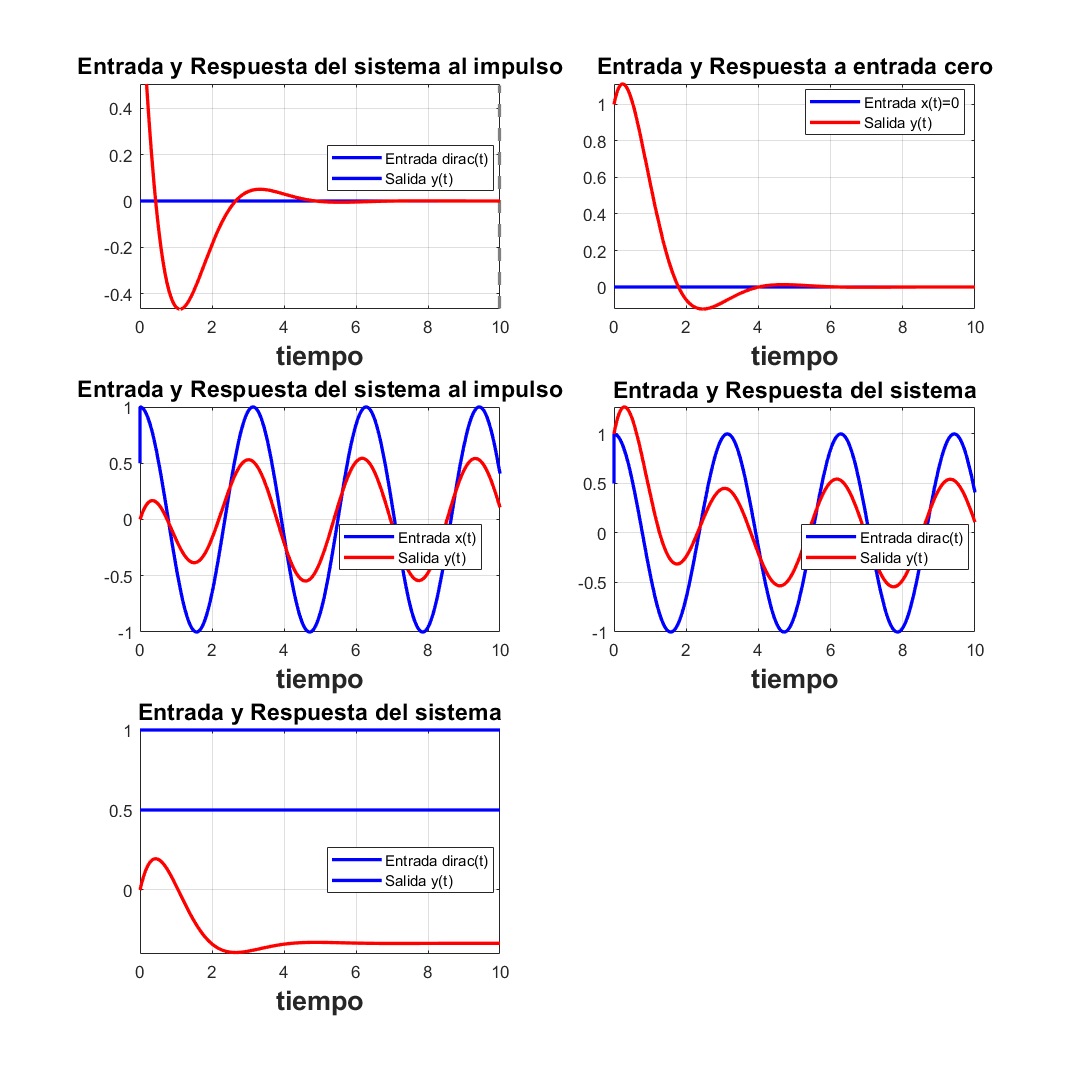

grafo(imp,en0,es0,rt,te,t0,xi)